
close all
clear

%% set nice plotting
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultGraphplotInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(groot, 'defaultAxesYGrid','on')
set(groot, 'defaultAxesXGrid','on')
set(groot, 'defaultAxesBox','on')
set(groot, 'defaultAxesYMinorTick','on')
set(groot, 'defaultAxesXMinorTick','on')
set(groot, 'defaultAxesYMinorGrid','on','defaultAxesYMinorGridMode','manual')
set(groot, 'defaultAxesXMinorGrid','on','defaultAxesXMinorGridMode','manual')
set(groot, 'defaultAxesFontSize', 14)
set(groot, 'defaultColorbarFontSize',12)
set(groot, 'defaultLegendFontSize', 10)
set(groot, 'defaultTextFontSize', 14)



## Main

w_all =     0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050


w_all =     0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050


w_all =     0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050


w = 12.5000

w = 12.5000

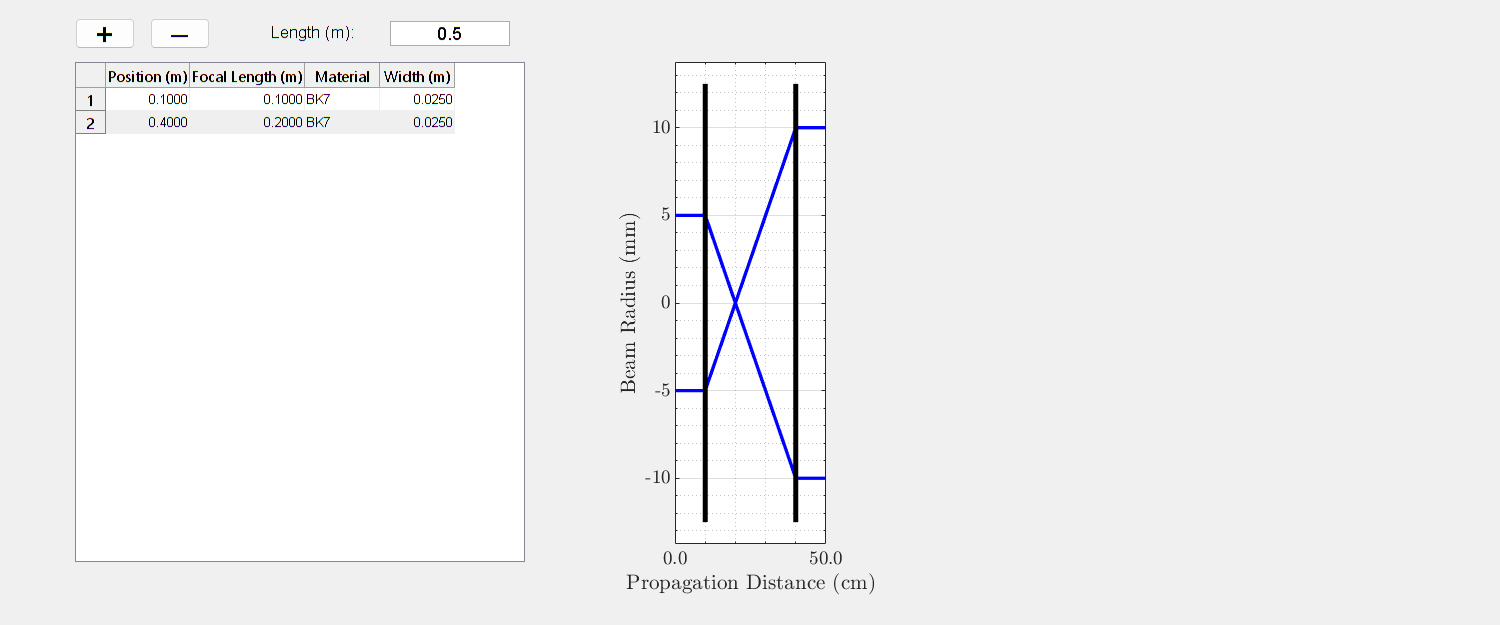

ray_trace_ui_with_table()

## Plot Ray Traces

function ray_trace_ui_with_table
    % Define initial laser and lens environment
    laser = struct();
    laser.energy = 5e-3;
    laser.width = 10e-3;
    laser.wavelength = 800e-9;
    laser.duration = 50e-15;

    environment.length = 0.5;
    environment.lenses = [
        struct('position', 0.1, 'focal_length', 0.1, 'width', 25e-3, 'material', 'BK7')
        struct('position', 0.4, 'focal_length', 0.2, 'width', 25e-3, 'material', 'BK7')
    ];

    % Set up figure and UI layout
    fig = figure('Name', 'Ray Tracer', ...
        'Position', [100, 100, 1200, 500]);

    ax = axes('Parent', fig, 'Units', 'normalized', ...
        'Position', [0.45, 0.13, 0.5, 0.77]);
    hold(ax, 'on');

    % Create global state
    global STATE
    STATE.laser = laser;
    STATE.environment = environment;
    STATE.ax = ax;

    % Launch table
    launchLensTable(fig);


    % Initial plot
    updateMultiLensRayPlot();
end

function updateMultiLensRayPlot()
    global STATE
    cla(STATE.ax); hold(STATE.ax, 'on');

    env = STATE.environment;
    laser = STATE.laser;

    lambda = laser.wavelength;
    w0 = laser.width / 2;
    q = 1i * pi * w0^2 / lambda;

    lenses = sortrows(struct2table(env.lenses), 'position');
    lenses = table2struct(lenses);

    z_all = []; w_all = [];
    z_start = 0;

    for i = 1:length(lenses)+1
        if i <= length(lenses)
            z_end = lenses(i).position;
        else
            z_end = env.length;
        end

        z_seg = linspace(z_start, z_end, 200);
        q_seg = propagateGaussianABCD(q, z_seg - z_start);
        w_seg = getBeamRadius(q_seg, lambda);

        z_all = [z_all, z_seg];
        w_all = [w_all, w_seg];

        if i <= length(lenses)
            q = q_seg(end);
            f = lenses(i).focal_length;
            M = [1 0; -1/f 1];
            q = (M(1,1)*q + M(1,2)) / (M(2,1)*q + M(2,2));
            z_start = z_end;
        end
    end

    plot(STATE.ax, z_all,  w_all*1e3, 'b', 'LineWidth', 2);
    plot(STATE.ax, z_all, -w_all*1e3, 'b', 'LineWidth', 2);

    % Draw lenses
    for i = 1:length(lenses)
        x = lenses(i).position;
        w = lenses(i).width * 1e3 / 2;
        line(STATE.ax, [x x], [-w w], 'Color', 'k', 'LineWidth', 3);
    end

    ylabel(STATE.ax, 'Beam Radius (mm)');
    xlim(STATE.ax, [0 env.length]);
    ylim(STATE.ax, [-1.1*max([lenses.width w_all]), 1.1*max([lenses.width w_all])].*0.5e3);
    grid(STATE.ax, 'on');

    xticks = get(STATE.ax, 'XTick');
    xticklabels = arrayfun(@(x) sprintf('%.1f', x*100), xticks, 'UniformOutput', false);
    set(STATE.ax, 'XTickLabel', xticklabels);
    xlabel(STATE.ax, 'Propagation Distance (cm)');
end

function launchLensTable(fig)
    global STATE

    lenses = STATE.environment.lenses;
    n = length(lenses);

    data = cell(n, 4);
    for i = 1:n
        data{i, 1} = lenses(i).position;
        data{i, 2} = lenses(i).focal_length;
        data{i, 3} = lenses(i).material;
        data{i, 4} = lenses(i).width;
    end

    column_names = {'Position (m)', 'Focal Length (m)', 'Material', 'Width (m)'};

    STATE.uitableHandle = uitable(fig, 'Data', data, ...
        'ColumnName', column_names, ...
        'ColumnEditable', [true true true true], ...
        'Units', 'normalized', ...
        'Position', [0.05, 0.1, 0.3, 0.8], ...
        'CellEditCallback', @onTableEdit);
    % Add '+' button (Add Lens)
    btnAddLens = uicontrol(fig, 'Style', 'pushbutton', 'String', '+', ...
        'Units', 'normalized', 'Position', [0.05, 0.92, 0.04, 0.05], ...
        'FontSize', 18, 'Callback', @addLensCallback);
    
    % Add '−' button (Remove Lens)
    btnRemoveLens = uicontrol(fig, 'Style', 'pushbutton', 'String', '−', ...
        'Units', 'normalized', 'Position', [0.10, 0.92, 0.04, 0.05], ...
        'FontSize', 18, 'Callback', @removeLensCallback);
    
    % Simulation Length label (compact)
    uicontrol(fig, 'Style', 'text', 'String', 'Length (m):', ...
        'Units', 'normalized', 'Position', [0.18, 0.915, 0.1, 0.05], ...
        'HorizontalAlignment', 'left', 'FontSize', 10);
    
    % Simulation Length edit box (compact)
    editLength = uicontrol(fig, 'Style', 'edit', ...
        'String', num2str(STATE.environment.length), ...
        'Units', 'normalized', 'Position', [0.26, 0.925, 0.08, 0.04], ...
        'FontSize', 11, 'Callback', @updateLengthCallback);

end

function onTableEdit(src, event)
    global STATE

    data = get(src, 'Data');
    n = size(data, 1);

    new_lenses = repmat(struct('position', 0, 'focal_length', 0, ...
        'width', 0, 'material', 'BK7'), 1, n);

    for i = 1:n
        new_lenses(i).position     = data{i, 1};
        new_lenses(i).focal_length = data{i, 2};
        new_lenses(i).material     = data{i, 3};
        new_lenses(i).width        = data{i, 4};
    end

    STATE.environment.lenses = new_lenses;
    updateMultiLensRayPlot();
end

function q_vals = propagateGaussianABCD(q_in, dz)
    % dz: vector of distances (can be multiple points)
    A = 1; B = dz;
    C = 0; D = 1;
    q_vals = (A .* q_in + B) ./ (C .* q_in + D);
end


function w = getBeamRadius(q, lambda)
    % Extract beam radius from q-parameter
    w = sqrt(-lambda ./ (pi * imag(1 ./ q)));
end


function addLensCallback(~, ~)
    global STATE
    % Add a new lens with default parameters at the end of the environment.lenses array
    newLens = struct('position', 0.25, 'focal_length', 0.1, 'width', 25e-3, 'material', 'BK7');
    STATE.environment.lenses(end+1) = newLens;
    
    % Refresh the table and plot
    updateLensTable();
    updateMultiLensRayPlot();
end

function updateLengthCallback(src, ~)
    global STATE
    newLength = str2double(get(src, 'String'));
    if isnan(newLength) || newLength <= 0
        % Reject invalid input, reset to previous valid value
        set(src, 'String', num2str(STATE.environment.length));
        errordlg('Please enter a positive numeric value for length', 'Invalid Input');
        return
    end
    STATE.environment.length = newLength;
    updateMultiLensRayPlot();
end

function removeLensCallback(~, ~)
    global STATE

    if isempty(STATE.environment.lenses)
        return % no lenses to remove
    end

    % Remove last lens from the array
    STATE.environment.lenses(end) = [];

    % Update table and plot
    updateLensTable();
    updateMultiLensRayPlot();
end


function updateLensTable()
    global STATE
    lenses = STATE.environment.lenses;
    n = length(lenses);
    data = cell(n, 4);
    for i = 1:n
        data{i, 1} = lenses(i).position;
        data{i, 2} = lenses(i).focal_length;
        data{i, 3} = lenses(i).material;
        data{i, 4} = lenses(i).width;
    end

    set(STATE.uitableHandle, 'Data', data);
end